## Metody numeryczne – Laboratorium 2

### Zadanie 2. Pęcherzykowy kwadrat

Agnieszka Delmaczyńska, 184592

Informatyka 2021/2022, semestr 4, grupa 1

**Zadanie.** Wypełnić pole kwadratu o boku a (np. 1) pęcherzykami o losowych wielkościach w liczbie n_max, czyli losowo rozmieszczonymi okręgami o losowo wybranych promieniach z zakresu <0, r_max>, które nie przecinają się ze sobą. Można zaszaleć z pętlami.

Na początek czyszczę Okno poleceń i pole Workspace.

clc;          % clear Command Window
clear;        % clear Workspace

Ustawiam dane parametry: a, r_max (r_max < a/2) , n_max (100...10 000 lub więcej).

a = 1;        % kwadrat o boku 5
r_max = a/5;  % maksymalny promień pęcherzyków, r_max < a/2
n = 0;        % początkowa liczba pęcherzyków
n_max = 100;  % maksymalna liczba pęcherzyków, (100...10 000 lub więcej)

Inicjalizuję wektpry, aby później zapamiętać parametry okręgu w wektorach x(n), y(n), r(n) (indeks n).

% zapamiętać parametry okręgu w wektorach x(n), y(n), r(n) (indeks n)
v_x = [];
v_y = [];
v_r = [];

Inicjalizuję wektor powierzchni okręgu

% zapamiętać aktualną wartość powierzchni okręgu
areas = [];
area = 0;

Inicjalizuję wektor liczby losowań potrzebnych do utworzenia (i narysowania) n‐tego okręgu.

% wektor przechowuje ile razy wykonane zostało losowanie, by uzyskać dany pęcherzyk
v_how_many_draws = [];
% liczba losowań
number_of_draws = 0;

Pętla while rysowania pęcherzyków, dopóki aktualna liczba pęcherzyków nie przekracza wart. max. == n_max.

Inicjalizuję zmienną logiczną, która określa, czy znaleziono miejsce dla nowego pęcherzyka. Przystępujemy do pierwszego losowania.

Do losowania parametru x, y, r bieżącego okręgu i skalowania do wart. maksymalnej a, r_max, używam funkcji rand.

Następnie sprawdzam warunek, czy wylosowany okrąg mieści się w kwadracie. Jeśli się mieści, przypisz space_for_the_bubble_was_found = true, wyjdź z zagnieżdżonej pętli while i przyjmij wartości wylosowane jako parametry dla nowego okręgu.

Na końcu inkrementuję liczbę losowań. Jeśli okrąg nie zostałby wylosowany, ponownie wykonujemy losowanie i inkrementujemy liczbę losowań daneg pęcherzyka.

% dopóki aktualna liczba pęcherzyków nie przekracza wart. max. == n_max
while(n<n_max)
    space_for_the_bubble_was_found = false;
    while(space_for_the_bubble_was_found == false)
        % do losowania parametru x, y, r bieżącego okręgu, użyć funkcji rand
        % i skalowania do wart. maksymalnej a, r_max
        x = a*rand(1);
        y = a*rand(1);
        r = r_max * rand(1);
        % sprawdzać czy wylosowany okrąg mieści się w kwadracie
        if(x+r < a && x-r > 0 && y-r>0 && y+r<a)
            % jeśli się mieści, wyjdź z pętli
            space_for_the_bubble_was_found = true;
        end
        % inkrementuj liczbę losowań
        number_of_draws = number_of_draws + 1;
    end

Następnie przechodzimy do sprawdzenia, czy nasz planowany nowy pęcherzyk, którego parametry już mamy, nie przecina się z żadnym z wcześniej narysowanych i zapamiętanych okręgów. Przyjmujemy zmienną logiczną if_crossed = false.

Sprawdzamy to poprzez przekukanie pętlą for wszystkich dotychczasowych pęcherzyków.

Sprawdzamy warunkiem if, czy okręgi na siebie nie nachodzą. Jeśli nachodzą, zapamiętujemy ten fakt w zmiennej logicznej if_crossed.

    % sprawdzać, czy nie przecina się z żadnym z wcześniej narysowanych
    % i zapamiętanych okręgów
    if_crossed = false;
    % pętla po wszystkich narysowanych i zapamiętanych pęcherzykach    
    for i = 1:n                 
            dist_x = x-v_x(i);
            dist_y = y-v_y(i);
            dist = sqrt(dist_x*dist_x + dist_y*dist_y);
            % sprawdza, czy okręgi się na siebie nie nachodzą,
            % nie będą rysowane jeden w drugim
            if(dist <= v_r(i) + r)  
                % po odnotowaniu przecięcia bieżącego okręgu z którymkolwiek
                % narysowanym ustawić zmienną logiczną zapamiętująca ten fakt
                if_crossed = true;                                   
            end        
        end

Jeśli przecięcia nie było (kolizji), to możemy inkrementować obecną liczbę pęcherzyków.

Funkcją axis equal; wyrównujemy skalę osi x i y. Rysujemy nowy pęcherzyk funkcją plot_circ i dodajemy do tego samego rysunku pęcherzyków.

        % jeśli nie było przecięcia z innym wcześniejszym okręgiem              
        if (if_crossed == false)        
            % to inkrementować liczbę wszystkich okręgów (pęcherzyków)
            n  = n + 1;             
            
            % wyrównać skalę osi x i y
            axis equal;             
            plot_circ(x, y, r);
            hold on;     

Zapamiętujemy liczbę losowań dla obecnego pęcherzyka i czyścimy ją dla kolejnego przypisując 0. Dopisujemy jego parametry do wektorów x, y, r. Dodajemy jego powierzchnię do poprzedniej powierzchni wszystkich okręgów i przechowujemy historię wzrostu powierzchni w wketorze areas.

Ostatecznie wypisujemy na konsolę bieżąca wartość n i powierzchni całkowitej i wstrzymujemy program na ułamek sekundy, aby zaktualizować wykres z narysowanym nowym okręgiem.

        % zapamiętać liczbę losowań dla obecnego pęcherzyka
        v_how_many_draws(n) = number_of_draws;
        % liczba losowań nowa dla kolejnego pęcherzyka
        number_of_draws = 0;    
        
        % dopisać jego parametry do wektorów x, y, r
        v_x(n) = x;             
        v_y(n) = y;
        v_r(n) = r;

        % dodać jego powierzchnię do poprzedniej powierzchni wszystkich okręgów
        area = area + pi*r*r;   
        % przechować historię wzrostu powierzchni
        areas(n) = area;        
       
        % wypisać na konsolę bieżąca wartość n i powierzchni całkowitej
        fprintf(1, ' %s%5d%s%.3g\r ', 'n =', n, ' S = ', area) 
        % wstrzymać program na ułamek sekundy, aby zaktualizować wykres
        % z narysowanym nowym okręgiem
        pause(0.01);           
    end
end

 n =    1 S = 0.026
  n =    2 S = 0.0405
  n =    3 S = 0.161
  n =    4 S = 0.166
  n =    5 S = 0.166
  n =    6 S = 0.17
  n =    7 S = 0.198
  n =    8 S = 0.199
  n =    9 S = 0.199
  n =   10 S = 0.204
  n =   11 S = 0.224
  n =   12 S = 0.225
  n =   13 S = 0.233
  n =   14 S = 0.235
  n =   15 S = 0.236
  n =   16 S = 0.239
  n =   17 S = 0.242
  n =   18 S = 0.243
  n =   19 S = 0.245
  n =   20 S = 0.246
  n =   21 S = 0.253
  n =   22 S = 0.253
  n =   23 S = 0.254
  n =   24 S = 0.254
  n =   25 S = 0.261
  n =   26 S = 0.261
  n =   27 S = 0.261
  n =   28 S = 0.266
  n =   29 S = 0.276
  n =   30 S = 0.278
  n =   31 S = 0.289
  n =   32 S = 0.289
  n =   33 S = 0.289
  n =   34 S = 0.29
  n =   35 S = 0.292
  n =   36 S = 0.298
  n =   37 S = 0.298
  n =   38 S = 0.303
  n =   39 S = 0.304
  n =   40 S = 0.305
  n =   41 S = 0.31
  n =   42 S = 0.31
  n =   43 S = 0.31
  n =   44 S = 0.313
  n =   45 S = 0.313
  n =   46 S = 0.327
  n =   47 S = 0.327
  n =   48 S = 0.3

Zatrzymujemy dodawanie do obecnego rysunku i zapisujemy go do pliku pecherzyki.png.

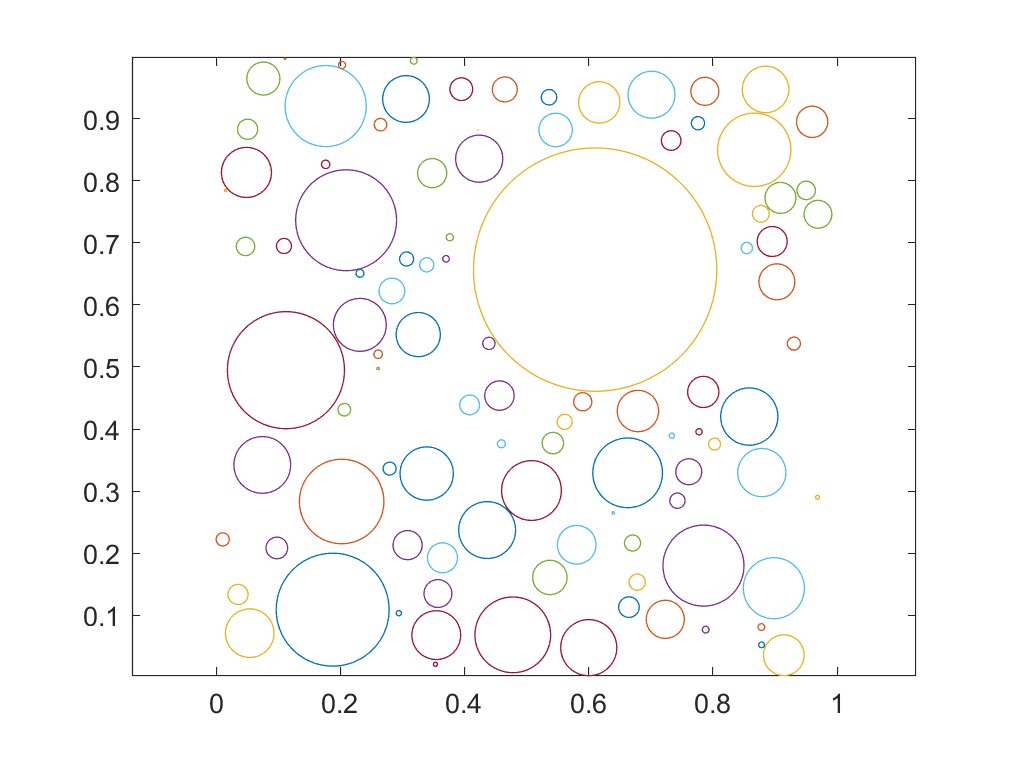

hold off;
saveas(gcf,'pecherzyki.png');

Wyświetlamy dwa wykresy: Powierzchni całkowitej i Średniej liczby losowań, posiadające opisy osi i tytuły oraz linie siatki pomocniczej funkcją grid on. Na końcu zapisujemy wykresy do plików wykres1.png i wykres2.png.

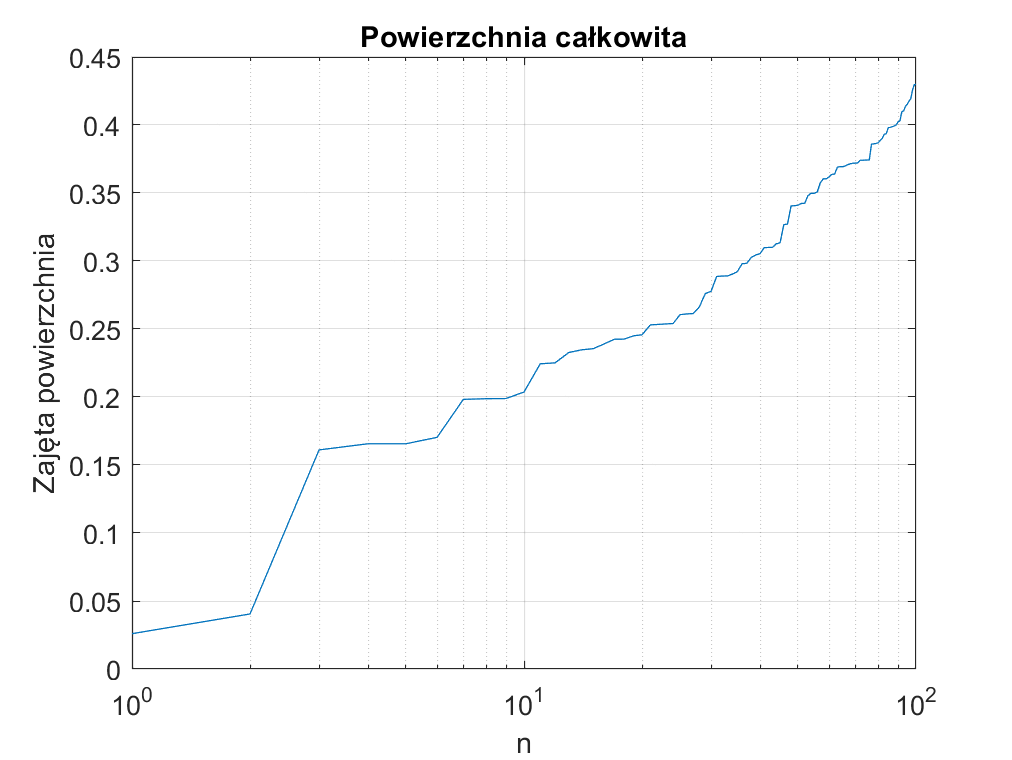

% wykres Powierzchni całkowitej
figure('Name', 'Powierzchnia całkowita');   
semilogx(1:n, areas);
title('Powierzchnia całkowita');
xlabel('n');
ylabel('Zajęta powierzchnia');
grid on;
saveas(gcf,'wykres1.png');

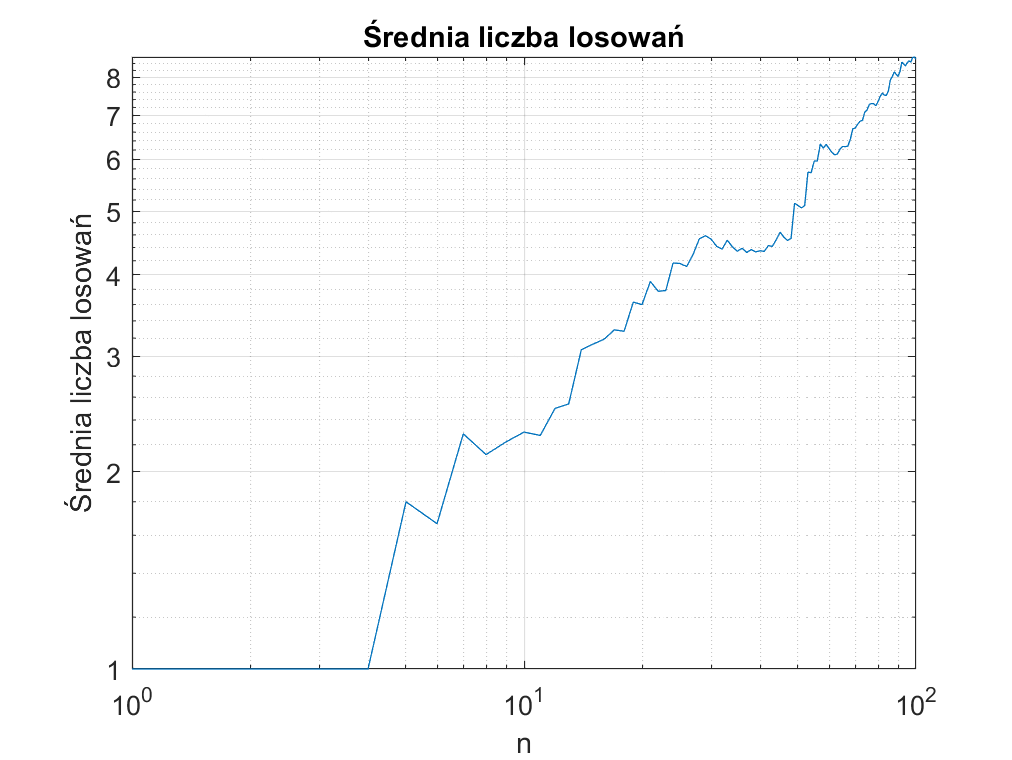

% wykres Średniej liczby losowań
figure('Name', 'Średnia liczba losowań');   
loglog(cumsum (v_how_many_draws)./(linspace(1,n,n)));
title('Średnia liczba losowań');
xlabel('n');
ylabel('Średnia liczba losowań');
grid on;
saveas(gcf,'wykres2.png');

Dodatek: definicja użytej funkcji

% funkcja do rysowania okręgu o zadanym środku (X,Y) i promieniu R

function plot_circ(X, Y, R)
    theta = linspace(0,2*pi);
    x = R*cos(theta) + X;
    y = R*sin(theta) + Y;
    plot(x,y)
end